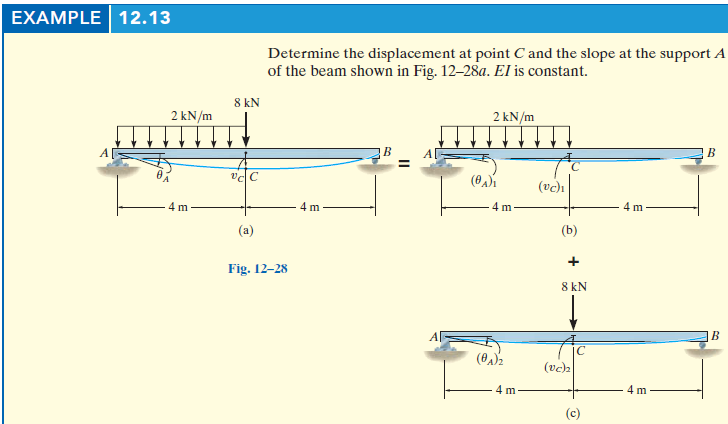

# beam

u = symunit;
b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 8*u.m);
b = b.add('distributed', 'force', -2*u.kN/u.m, [0 4]*u.m);
b = b.add('applied', 'force', -8*u.kN, 4*u.m);
b.L = 8*u.m;

# elastic curve

[y dy m v w r] = b.elastic_curve([], 'factor'); %#ok
y

$$y(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(x^{3}-20\,x^{2}\,m+672\,m^{3}\right)}{12\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 4\,m\\ -\frac{\left(x-8\,m\right)\,\left(3\,x^{2}-48\,x\,m+40\,m^{2}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }4\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{x^{3}-15\,x^{2}\,m+168\,m^{3}}{3\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 4\,m\\ -\frac{9\,x^{2}-144\,x\,m+424\,m^{2}}{3\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }4\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -x\,\left(x-10\,m\right)\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 4\,m\\ -6\,\left(x-8\,m\right)\,\mathrm{kN} & \text{ if }4\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -2\,\left(x-5\,m\right)\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 4\,m\\ -6\,\mathrm{kN} & \text{ if }4\,m<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -2\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 4\,m\\ 0 & \text{ if }4\,m<x \end{array}\right.$$

addvar(y);

# reactions

Ra = r.Ra

$$Ra = 10\,\mathrm{kN}$$

Rb = r.Rb

$$Rb = 6\,\mathrm{kN}$$

# slopes and deflections

dy_A = dy(0)

$$dy\_A = -\frac{56}{\text{E}\,\text{I}}\,\mathrm{kN}\,m^{2}$$

y_C = y(4*u.m)

$$y\_C = -\frac{416}{3\,\text{E}\,\text{I}}\,\mathrm{kN}\,m^{3}$$